# 3D Ball trajectory - while loop

This code shows how to numerically, using 'for' or 'whole' lop can model a system with air resitance (Drag) chich cannot be solved analytically. 

Note; this code might not be physically correct, its purpose it so show syntax and precess behind way to do numerical integration which wooyld be otherwise difficult or impossible.

## Equatins derived/used 


$$\textrm{Re}=\frac{\rho_{\textrm{air}} U_b 2R_b }{\mu }$$
            
$$\mu =1\ldotp 789\times {10}^{-5}$$



$$C_D =29\ldotp 52\;{\textrm{Re}}^{-1\ldotp 006} +0\ldotp 4438$$



$$\vec{D} =\frac{1}{2}\rho \;|U|\vec{U} A\;C_D \;$$
                    
$$\vec{D} ={m\vec{{\mathrm{a}}_D } } \to {\vec{a_D } } =\frac{\vec{D} }{m}$$



$$\vec{a_D } =\frac{1}{2m}\rho_{\textrm{air}} \;|U|\vec{U} A_{\textrm{sphere}} \;C_D$$



$$\vec{M} =\frac{16}{3}\pi^2 R^3 \rho_{\textrm{air}} \left(\vec{\omega} \times \vec{U} \right)$$
            
$$\vec{a_M } =\frac{\vec{M} }{m}$$


## Ball properties

D = 22e-2;          % ball diameter [m]
m = 0.44;           % weight [kg] (.41 - .45)
    R = D/2;        % radius [m]
    A = 2*pi*R^2;   % projected area [m^2]

## Local conditions

g = 9.81;           % gravitational acceleration [m/s2]
mu = 1.789e-5;      % [Pa.s] viscosity
rho = 1.225;        % air density [kg/m3]

## Initial conditions input

###     Starting points:

X0 = 0; % positions towards goal from datum [m]
Y0 = 0; % position left/right from datum [m]
Z0 = 0; % position up/down from datum [m]    

###     Initial velocity:

U0 = 80; % m/s initial velocity (world record is 45m/s) [m/s]
  yaw = -1; % left/right andgle og kick [deg]
pitch = 30; % height angle of kick [deg]

###     spin of the ball:

RPMx = 0;   % [rpm]
RPMy = -20; % frontspin/ backspin [rpm]
RPMz = -20; % sidespin [rpm]

% how 'fine' is the numerical approxiamtion
% smaller time step, more precission
t = 0.005; %timestep

## Calculations from initial conditions

###     Degrees into radians

Because calculation with standard units is adviseable

psi = deg2rad(yaw);     % degree -> radians
theta = deg2rad(pitch); % degree -> radians

r = [X0; Y0; Z0];       % creating x,y,z vector  [m]

w = [RPMx ; RPMy; RPMz].*(2*pi/60); % angular velocity vector

U = [U0*cos(psi)*cos(theta);
    -U0*sin(psi);
     U0*cos(psi)*sin(theta)]; % velocity vector [m/s]

Calculating rdat of sphere. Note that the drag coefficient (from Schlichting - Boundary-layer theory) of sphere is function of Reynolds number

Re = abs(2* rho*R/mu*U);                % Reynolds number [-] 
Cd = real(29.5.*Re.^(-1.006)+0.4438);   % Drag coefficient[-]

D = -rho.*U.^2.*A.*Cd./2 .*sign(U); % Total Drag [N]

M = 16/3*pi^2*R^3*rho*cross(w,U);   % Magnus force [N] (lift due to spin)


$$F=\mathrm{mass}\times \mathrm{acceleration}$$


acc_m = M./m;                       % acceleration due to Magnus force
acc_d = D./m;                       % acceleration due to Drag force
acc_g = [0;0;-g];                   % acceleration due to gravity
    acc = acc_d + acc_m + acc_g;    % total acceleration [m/s2]

## Itearations

In this example '**while**' loop is used. However; usuallly 'for' loop is preferred because of better control and less room for computer crashing errors

i = 1;                          % starting counter at 1
        while r(3,i) >= 0       % checking height from ground is positive
i = i+1;                        % increasing the counter by one
        % note: first positions are occupied by initial conditions

    if i > 4000     % fail safa
    break           %if iterations are eyond 4000 the loop will end
    end
        %     SUVAT
        dU(:,i-1) = acc(:,i-1).*t;  % change in velocity = a * t
        dr(:,i-1) = U(:,i-1).*t;    % change in position = v * t

        U(:,i) = U(:,i-1)+dU(:,i-1); % new velocity [m/s]
        r(:,i) = r(:,i-1)+dr(:,i-1); % new position [m]

    Re(:,i) =abs(2* rho*R/mu*U(:,i)); % new reaynolds number [-]
    Cd(:,i) = 29.5.*Re(:,i).^(-1.006)+0.4438; % new drag coefficient [-]

    D(:,i) = -rho.*U(:,i).^2.*A.*Cd(:,i)./2 .*sign(U(:,i)); % new total drag [N]

    M(:,i) = 16/3*pi^2*R^3*rho * cross(w,U(:,i)); % new magnus force [N]

acc_m(:,i) = M(:,i)./m;                 % new acceeration due to Magnus [m/s2]
acc_d(:,i) = D(:,i)./m ;                % new acceeration due to Drag   [m/s2]
    acc(:,i) = acc_d(:,i) + acc_m(:,i) + acc_g; % new total acceeration [m/s2]

        end


## Plotting the results

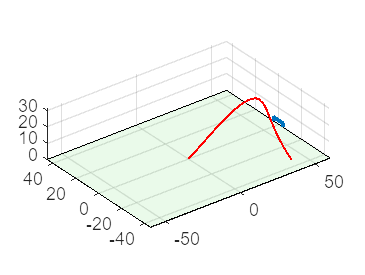

field_l = 120; % 90-120
field_w = 90; % 45-90

fill3([-field_l/2 field_l/2 field_l/2 -field_l/2],...
      [-field_w/2 -field_w/2 field_w/2 field_w/2],...
      [0 0 0 0],[0.2 0.8 0.2],'FaceAlpha',0.1)
  grid on;
  zlim([0 2*max(r(3,:))])
%   xlim([-0.1*field_l/2 field_l/2])
%   ylim([-0.2*field_w/2 0.2*field_w/2])

axis equal
hold on

plot3(r(1,:),r(2,:),r(3,:),'r','LineWidth',1)
line([field_l/2 field_l/2 field_l/2 field_l/2],...
    [-3.6576 -3.6576 3.6576 3.6576],...
    [0 2.4384 2.4384 0],'LineWidth',2)
hold off


disp(['Final destination ',num2str(r(1:2,end)')])

Final destination 42.7323     -34.1172


disp(['Max Re ',num2str(max(max(Re)))])

Max Re 1043525.0947
